%Black-Litterman Portfolio implementation by K.Tomov

T = readtable('BLportfolio.xlsx'); %historical log-returns
assetNames = ["WNS","GPN","JD","LOGI","VIPS","BIDU"];
benchmarkName = "NYSE";
head(T(:,["Date" benchmarkName assetNames]))

       Date        NYSE      WNS      GPN        JD       LOGI      VIPS      BIDU 
    ___________    _____    _____    ______    ______    ______    ______    ______

    14-May-2020    10927    40.68    159.82    45.736    49.579     16.29     96.02
    15-May-2020    10947    40.14    165.22    47.502    49.899    16.436     99.86
    18-May-2020    11402    42.77    175.17    51.874    51.433    16.212    107.59
    19-May-2020    11249    43.25    174.99    50.687    52.346     15.51    109.75
    20-May-2020    11420    43.04    175.53    50.734    53.899    14.827    108.52
    21-May-2020    11352    41.73    171.58    49.109    52.186    14.729    110.03
    22-May-2020    11332    41.95    171.91    46.614  

retnsT = tick2ret(T(:, 2:end));
assetRetns = retnsT(:, assetNames);
benchRetn = retnsT(:, "NYSE");
numAssets = size(assetRetns, 2);

v = 5;  % total 5 views (BLACK LITTERMAN ASSUMPTIONS) <Portfolio weights optimized on factors
P = zeros(v, numAssets);
q = zeros(v, 1);
Omega = zeros(v);

% View 1
P(1, assetNames=="JD") = 1; %<- needs reformulation
q(1) = 0.40;%<- needs reformulation
Omega(1, 1) = 1e-8;%<- needs reformulation

% View 2
P(2, assetNames=="LOGI") = 1; %<- needs reformulation
q(2) = 0.1;%<- needs reformulation
Omega(2, 2) = 1e-5;%<- needs reformulation

% View 3 (one will outperform the other) EI: VIPS will outperform GPN by X%
P(3, assetNames=="VIPS") = 1; %<- needs reformulation
P(3, assetNames=="GPN") = -1; %<- needs reformulation
q(3) = 0.25;%<- needs reformulation (mean returns estimates)
Omega(3, 3) = 1e-6;%<- needs reformulation (uncertainty function)

% View 4
P(4, assetNames=="BIDU") = 1; %<- needs reformulation
q(4) = 0.1;%<- needs reformulation
Omega(4, 4) = 1e-6;%<- needs reformulation

% View 5
P(5, assetNames=="WNS") = 1; %<- needs reformulation
q(5) = 0.10;%<- needs reformulation
Omega(5, 5) = 1e-7;%<- needs reformulation
%_____________________________________________________________________________________________________


viewTable = array2table([P q diag(Omega)], 'VariableNames', [assetNames "View_Return" "View_Uncertainty"])  

viewTable = 5×8 table
    WNS    GPN    JD    LOGI    VIPS    BIDU    View_Return    View_Uncertainty
    ___    ___    __    ____    ____    ____    ___________    ________________

     0      0     1      0       0       0          0.4             1e-08      
     0      0     0      1       0       0          0.1             1e-05      
     0     -1     0      0       1       0         0.25             1e-06      
     0      0     0      0       0       1          0.1             1e-06      
     1      0     0      0       0       0          0.1             1e-07      


bizyear2bizday = 1/252;
q = q*bizyear2bizday; 
Omega = Omega*bizyear2bizday;

Sigma = cov(assetRetns.Variables);

tau = 1/size(assetRetns.Variables, 1);
C = tau*Sigma;

function [wtsMarket, PI] = findMarketPortfolioAndImpliedReturn(assetRetn, benchRetn)
% Find the market portfolio that tracks the benchmark and its corresponding implied expected return.
Sigma = cov(assetRetn);
numAssets = size(assetRetn,2);
LB = zeros(1,numAssets);
Aeq = ones(1,numAssets);
Beq = 1;
opts = optimoptions('lsqlin','Algorithm','interior-point', 'Display',"off");
wtsMarket = lsqlin(assetRetn, benchRetn, [], [], Aeq, Beq, LB, [], [], opts);
shpr = mean(benchRetn)/std(benchRetn);
delta = shpr/sqrt(wtsMarket'*Sigma*wtsMarket); 
PI = delta*Sigma*wtsMarket;
end

[wtsMarket, PI] = findMarketPortfolioAndImpliedReturn(assetRetns.Variables, benchRetn.Variables);

mu_bl = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu = inv(P'*(Omega\P) + inv(C));

mu_bl = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu = inv(P'*(Omega\P) + inv(C));

table(assetNames', PI*252, mu_bl*252, 'VariableNames', ["Asset_Name", ...
    "Prior_Belief_of_Expected_Return", "Black_Litterman_Blended_Expected_Return"])

ans = 6×3 table
    Asset_Name    Prior_Belief_of_Expected_Return    Black_Litterman_Blended_Expected_Return
    __________    _______________________________    _______________________________________

      "WNS"                   0.21253                                0.10007                
      "GPN"                   0.23706                                0.12305                
      "JD"                    0.23326                                0.39998                
      "LOGI"                    0.203                                 0.1057                
      "VIPS"                  0.21988                                0.37236                
      "BIDU"                  0.24259                                0.10173                


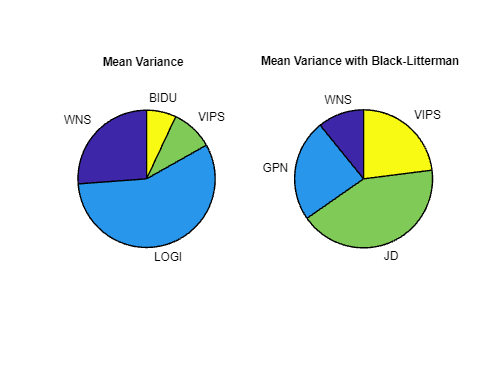

port = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance');
port = setAssetMoments(port, mean(assetRetns.Variables), Sigma);
wts = estimateMaxSharpeRatio(port);

portBL = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance with Black-Litterman');
portBL = setAssetMoments(portBL, mu_bl, Sigma + cov_mu);  
wtsBL = estimateMaxSharpeRatio(portBL);

ax1 = subplot(1,2,1);
idx = wts>0.001;
pie(ax1, wts(idx), assetNames(idx));
title(ax1, port.Name ,'Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
idx_BL = wtsBL>0.001;
pie(ax2, wtsBL(idx_BL), assetNames(idx_BL));
title(ax2, portBL.Name ,'Position', [-0.05, 1.6, 0]);

%weights distributed and compared with standard mean variance optimization in %
table(assetNames', wts, wtsBL, 'VariableNames', ["AssetName", "Mean_Variance","Mean_Variance_with_Black_Litterman"])

ans = 6×3 table
    AssetName    Mean_Variance    Mean_Variance_with_Black_Litterman
    _________    _____________    __________________________________

     "WNS"           0.26175                     0.10845            
     "GPN"        2.8119e-15                     0.23836            
     "JD"         3.0595e-14                     0.42324            
     "LOGI"          0.56982                  7.6978e-11            
     "VIPS"         0.098628                     0.22995            
     "BIDU"         0.069796                  8.4234e-16            
